% Exercise 1
% 

% data
y = rand(1,80) > 0.3;

% model fit
ypredict = rand(size(y)) > 0.5;

% Total model correctness
pctmodel = sum(ypredict==y) / length(y) * 100

pctmodel = 60


% Model correctness for 0 value
pctzeromodel = sum(ypredict==0) / length(y==0) * 100

pctzeromodel = 43.7500

% Exercise 2

heightM = 50 + 10*randn(1,100);
heightF = 45 + 9*rand(1,60);

weightM = 50 + 2*heightM + 10*randn(size(heightM));
weightF = 40 + 3*heightF + 10*randn(size(heightF));

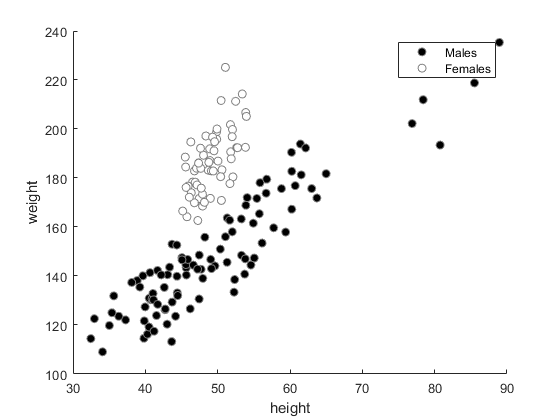

% Visualize the raw data
figure; hold on;
males = scatter(heightM , weightM,'k','filled');
females = scatter(heightF , weightF,'w','filled');

set([males females], 'MarkerEdgeColor', [.5 .5 .5]);
legend([males, females], {'Males' 'Females'})
xlabel('height')
ylabel('weight')

% prepare data
classMales = [heightM; weightM]';
classFemales = [heightF; weightF]';

ax = axis;

xvals = linspace(ax(1), ax(2));
yvals = linspace(ax(3), ax(4));

[xx, yy] = meshgrid(xvals,yvals);
gridX = [xx(:) yy(:)];

% Perform nearest-prototype classifier

% Find centres of the classes
centroidMales = mean(classMales, 1);
centroidFemales = mean(classFemales, 1);

% calculate the distance to class Males
distanceToMales = sqrt(sum((gridX - centroidMales).^2,2));
distanceToFemales = sqrt(sum((gridX - centroidFemales).^2,2));

% Create a decision boundary
% 1 for Males, 0 for Females
outputimage = distanceToMales < distanceToFemales;
outputimage = reshape(outputimage, [length(xvals) length(yvals)]);

% Calculate the model accuracy

% prepare full dataset data

X = [heightM' weightM'; ...
    heightF' weightF';];

y = [ones(length(heightM),1);
    zeros(length(heightF),1);];

% calculate the distance to class Males
distanceToMales = sqrt(sum((X - centroidMales).^2,2));
distanceToFemales = sqrt(sum((X - centroidFemales).^2,2));

% Suppose that calculated distance to males is lower than to females
pred = distanceToMales < distanceToFemales;

% Test how exactly the prediction is equal to the sample
pred = pred == y;

% Calculate accuracy
acc = sum(pred) / length(pred) * 100;

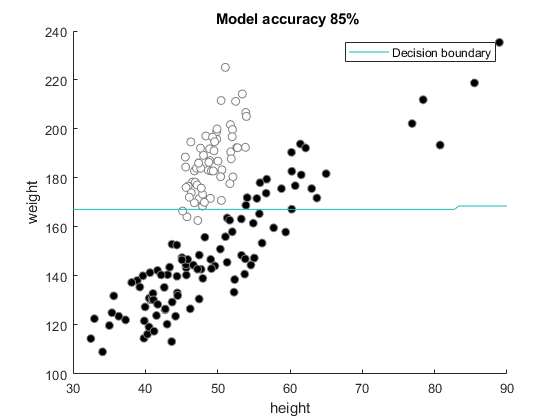

% Visualize the desicion boundary

[d, h2] = contour(xvals, yvals, outputimage, [.5 .5]);

legend(h2,"Decision boundary ");
title(sprintf("Model accuracy %.f%% %", acc))